% Define transfer function variable
s = tf('s');

%Used the equations in:
%https://ricopic.one/control/control_partial_06-06_06-6_Proportional-derivative_(PD)_controller_design.pdf
% And from youtube video: https://www.youtube.com/watch?v=4lRYUIhLYB8
% And look at this github: https://github.com/tu-darmstadt-ros-pkg/hector_quadrotor/blob/indigo-devel/hector_quadrotor_gazebo_plugins/src/gazebo_quadrotor_simple_controller.cpp

% Original open-loop system
%Needed to create the regulator
%Is the result of the prior system were the controller P(s) was equal 1.
G_orig = tf(0.6653 / (1.841 * s^2));  %Open loop transfer function
%G_orig = tf(0.6653 / (1.841 * s^2 + 0.6653)) %Closed loop transfer function

% Design specs
OS_percentage = 24; %Overshoot
T_s = 10; %Settling time in seconds

%Compute damping ratio from overshoot
zeta = -log(OS_percentage / 100) / sqrt(pi^2 + log(OS_percentage / 100)^2);

%Compute natural frequency from settling time
omega_n = 4 / (zeta * T_s);

%Compute desired pole location components
zeta_omega_n = zeta * omega_n   

zeta_omega_n = 0.4000

omega_d = omega_n * sqrt(1 - zeta^2) %Damped natural frequency

omega_d = 0.8805


%Desired pole locations
s_desired_plus = -zeta_omega_n + 1i * omega_d %Derrived equation

s_desired_plus = -0.4000 + 0.8805i

%s_desired_plus = -(4/T_s)*(1-1i*(pi/log(100/OS_percentage))); %Compressed version from PDF
s_desired_minus = -zeta_omega_n - 1i * omega_d;

%Phase of the open-loop G(s) at the desired pole
phi_G = angle(evalfr(G_orig, s_desired_plus));

%Angle from controller zero (phase angle method)
alpha_c = pi - phi_G;

%Zero location of the PD controller
z_c = real(s_desired_plus) + imag(s_desired_plus) / tan(alpha_c)

z_c = 0.3692


%Magnitude of G(s) at desired pole
G_at_pole = evalfr(G_orig, s_desired_plus)

G_at_pole = -0.2542 + 0.2910i


%Gain of the PD controller
K = 1 / abs((s_desired_plus - z_c) * G_at_pole)

K = 2.2137


KP = K * z_c

KP = 0.8173

KD = K

KD = 2.2137


%Define PD controller
D = K * (s + z_c)

D =
 
  2.214 s + 0.8173
 
Continuous-time transfer function.
Model Properties


%D = 1;

%PWM to Ang. Vel. Motor transfer function M(s)
%Derrived from O(s)/U(s) = 1/0.1115
M = (1) / (0.1115);

%Thrust function Y(s)
%Derrived from F(s)/O(s) = 1/13.4796
Y = (1) / (13.4796);

%Drone function P(s)
m = 1.7661 + 0.075; %(kg) Drone + raspberry pi
P = tf((1) / (m*s^2));

%Define transfer function for Bode plot
G = tf(D * M * Y * P)

G =
 
  1.473 s + 0.5438
  ----------------
     1.841 s^2
 
Continuous-time transfer function.
Model Properties


%G = minreal(G);
ZeroPoleForm = zpk(G)

ZeroPoleForm =
 
  0.80001 (s+0.3692)
  ------------------
         s^2
 
Continuous-time zero/pole/gain model.
Model Properties



%Ideal system
ideal_sys = tf(omega_n^2, [1, 2*zeta*omega_n, omega_n^2]);
disp('Ideal system: ');

Ideal system: 


stepinfo(ideal_sys)

ans = struct with fields:
         RiseTime: 1.5384
    TransientTime: 8.6895
     SettlingTime: 8.6895
      SettlingMin: 0.9177
      SettlingMax: 1.2400
        Overshoot: 24.0000
       Undershoot: 0
             Peak: 1.2400
         PeakTime: 3.5690

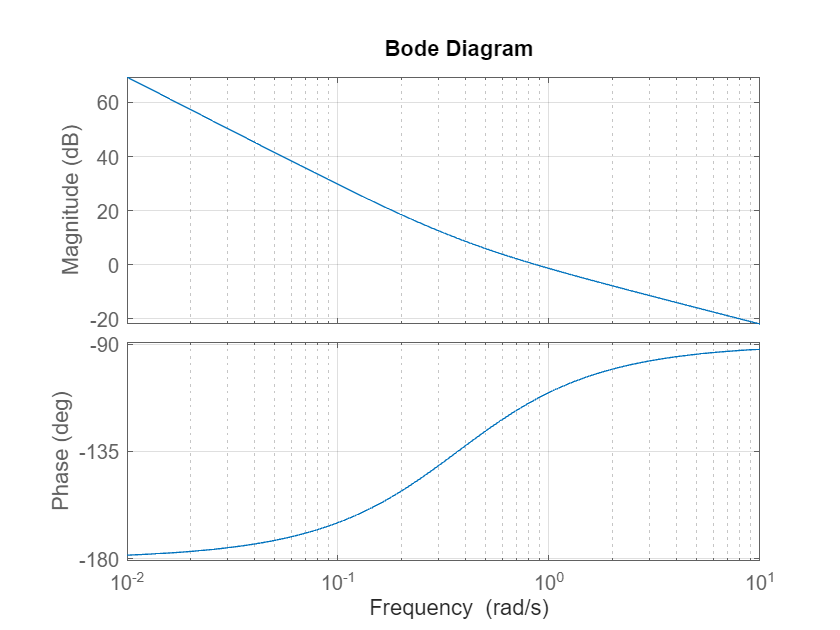


% Plot Bode diagram
bode(G)
grid on


% Display the phase- and gain margin
[GM, PM, Wcg, Wcp] = margin(G);
disp(['Phase Margin (degrees): ', num2str(PM)]);

Phase Margin (degrees): 66.9863


disp(['Gain Margin (dB): ', num2str(20*log10(GM))]);

Gain Margin (dB): -Inf



%Plot step respons
CL = feedback(G,1)

CL =
 
        1.473 s + 0.5438
  ----------------------------
  1.841 s^2 + 1.473 s + 0.5438
 
Continuous-time transfer function.
Model Properties


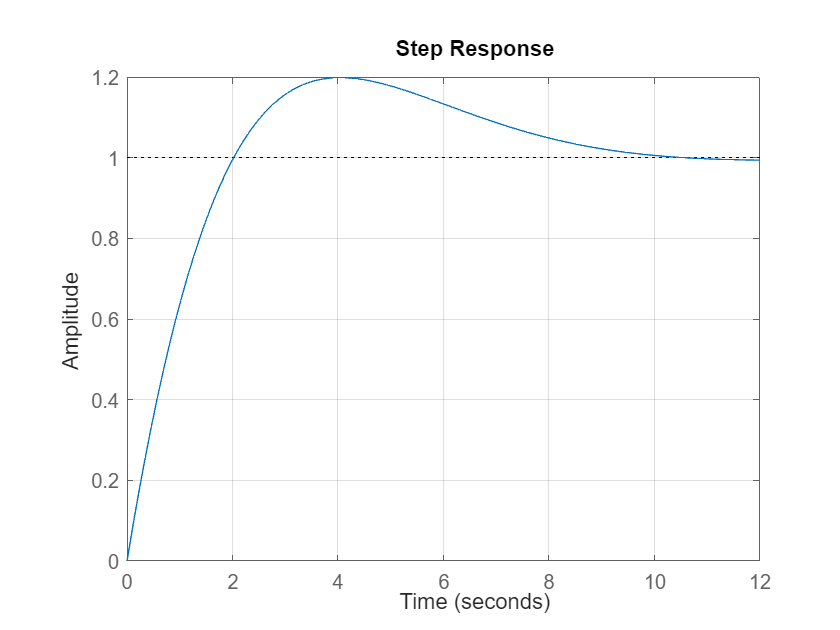

t = linspace(0, 10, 1000);
step(CL);
grid on;


%Get step response characteristics
S = stepinfo(CL);
%Display rise time
disp(['Rise Time: ', num2str(S.RiseTime), ' seconds'])

Rise Time: 1.5347 seconds


%Display overshoot
disp(['Overshoot: ', num2str(S.Overshoot), ' %'])

Overshoot: 19.8488 %


%Display settling time
disp(['Settling time: ', num2str(S.SettlingTime), ' seconds'])

Settling time: 9.0925 seconds


%Display peak time
disp(['Peak time: ', num2str(S.PeakTime), ' seconds'])

Peak time: 4.0295 seconds


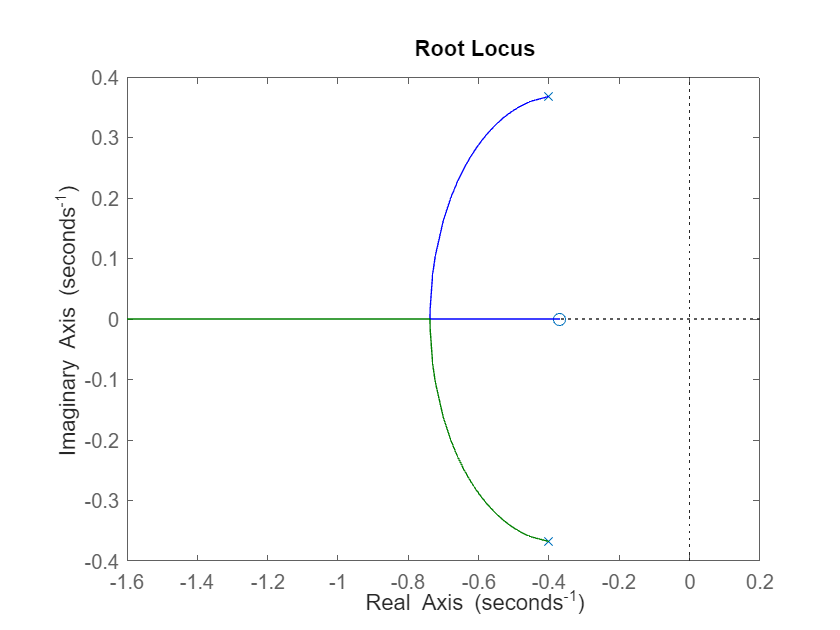


%Find poles:
rlocus(CL);

% Find and display poles
disp('Poles of the system:');

Poles of the system:


poles = pole(CL)

poles =   -0.4000 + 0.3679i
  -0.4000 - 0.3679i


% Find and display zeros
disp('Zeros of the system:');

Zeros of the system:


zeros_CL = zero(CL)

zeros_CL = -0.3692

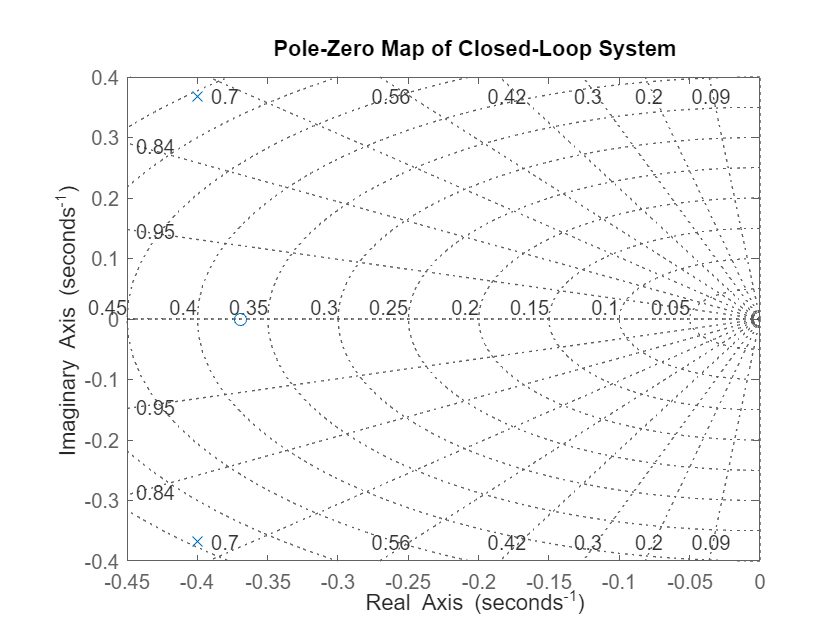


%Pole-Zero placement (Other method of mapping)
figure;
pzmap(CL);
title('Pole-Zero Map of Closed-Loop System');
grid on;


%Compute actual natural frequency
omega_n_measured = sqrt(real(poles(1))^2 + imag(poles(1))^2);
disp('Measured natural frequency:');

Measured natural frequency:


disp(omega_n_measured);

    0.5435



%Compute actual damping ratios for each pole
zeta_values = -real(poles) ./ abs(poles);
disp('Damping Ratios (zeta) computed:');

Damping Ratios (zeta) computed:


disp(zeta_values);

    0.7360
    0.7360




%CONTROL SYSTEM DESIGNER
%controlSystemDesigner(G);